# Examples 5.6 and 5.9: Residual Analysis and Cross-Validation for Heat Capacity

Note: this script reproduces Examples 5.6 (Section 5.2.2) and 5.9 (Section 5.2.5) of **Statistics for Chemical Engineers**: comparing Model I (quadratic) with Model II (linear) for heat capacity. Victor Z UW-Madison, 2020 use MSE and cdf to benchmark models

clc; clear all; close all hidden;

## Data

generate data (true model is Cp=a0+a1*T+a2*T^2) CP in cal/mol-K and T in K

a0=+0.6190e+1;
a1=+0.2923e-2;
a2=-0.7052e-6;
theta=[a0,a1,a2]';

% 3 sets of experiments at T=300K, T=400K, and T=500K
n=10;
N=3*n;
x1=linspace(300,300,n)';
x2=linspace(600,600,n)';
x3=linspace(900,900,n)';
 x=[x1; x2; x3];
    
% generate true outputs 
rng(0);
y1=a0+a1*x1+a2*x1.^2;
y2=a0+a1*x2+a2*x2.^2;
y3=a0+a1*x3+a2*x3.^2;
ytrue=[y1; y2; y3];

% add random noise to true outputs
sigma=0.1;
y=ytrue+normrnd(0,sigma,N,1);

## Model I

get model I

xsq=x.^2;
X=[ones(N,1),x,xsq];
Y=y;

thetaest=inv(X'*X)*X'*Y

thetaest =    6.1985e+00
   3.1794e-03
  -9.6020e-07


Yhat=X*thetaest;
eI=(Y-Yhat).^2;

## Model II

get model II

X2=[ones(N,1),x];
Y=y;

thetaest=inv(X2'*X2)*X2'*Y

thetaest =    6.4865e+00
   2.0271e-03


Yhat=X2*thetaest;
eII=(Y-Yhat).^2;

## Comparison

compare mse

mseI=mean(eI)

mseI =    1.6073e-02

mseII=mean(eII)

mseII =    1.7733e-02

## compare using cdf

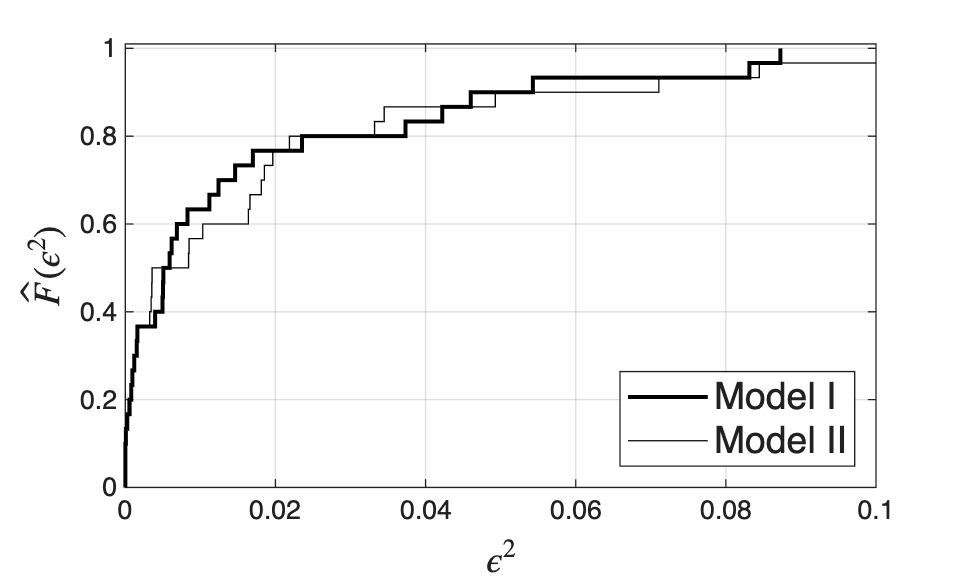

figure(1)
[F,t]=ecdf(eI);
stairs(t,F,'LineWidth',1.5,'Color','black')
hold on

[F,t]=ecdf(eII);
stairs(t,F,'black-','LineWidth',0.5)
hold on
xlabel('$\epsilon^2$','Interpreter','latex','FontSize',14)
ylabel('$\hat{F}(\epsilon^2)$','Interpreter','latex','FontSize',14)
legend('Model I', 'Model II','location','Southeast','FontSize',14)
axis([0 0.1 0 1.01])
grid on
print -depsc ch5_heat_cap_cdf.eps

## Cross-validation (Example 5.9)

lets do cross-validation (for first model)

% full data set
X=[ones(N,1),x,xsq];
Y=y;

% shuffle data
S = length(y);
idx = 1:1:S;
idxS = randperm(numel(idx));

% partitionindexes
idxP{1}=idxS(1:10);
idxP{2}=idxS(11:20);
idxP{3}=idxS(21:30);

% for all partitions
for k=1:3
    
% get testing data
Xp{k}=X(idxP{k},:);
Yp{k}=Y(idxP{k});

% get training data
Xt{k}=[];
Yt{k}=[];
for j=1:3
    if j == k
    else
    Xt{k}=[Xt{k}; X(idxP{j},:)];
    Yt{k}=[Yt{k}; Y(idxP{j});];
    end
end
% get model using training data
thetat{k}=inv(Xt{k}'*Xt{k})*Xt{k}'*Yt{k};

% test the model
Yhatp{k} = Xp{k}*thetat{k};
et{k} = (Yp{k}-Yhatp{k}).^2;
MSE(k) = mean(et{k});

end

MSEI=MSE'

MSEI =    1.7927e-02
   1.3293e-02
   1.8260e-02


sum(MSEI)

ans =    4.9480e-02

## lets do cross-validation (for second model)

% full data set
X=[ones(N,1),x];
Y=y;

% shuffle data
S = length(y);
idx = 1:1:S;
idxS = randperm(numel(idx));

% partitionindexes
idxP{1}=idxS(1:10);
idxP{2}=idxS(11:20);
idxP{3}=idxS(21:30);
N=10;

% for all partitions
for k=1:3
    
% get testing data
Xp{k}=X(idxP{k},:);
Yp{k}=Y(idxP{k});

% get training data
Xt{k}=[];
Yt{k}=[];
for j=1:3
    if j == k
    else
    Xt{k}=[Xt{k}; X(idxP{j},:)];
    Yt{k}=[Yt{k}; Y(idxP{j});];
    end
end
% get model using training data
thetat{k}=inv(Xt{k}'*Xt{k})*Xt{k}'*Yt{k};

% test the model
Yhatp{k} = Xp{k}*thetat{k};
et{k} = (Yp{k}-Yhatp{k}).^2;
MSE(k) = mean(et{k});

end

MSEII=MSE'

MSEII =    3.9173e-02
   2.2118e-02
   1.7356e-02


sum(MSEII)

ans =    7.8647e-02

## Note

As in the book, the cdf of the errors of Model I lies above that of Model II (smaller errors are more likely), and cross-validation confirms that Model I generalizes better.